## Problem 2.

Problem 1의 1차 시스템이 외부 입력 $r(t)$를 추종하기 위한 self-tuning controller를 설계하고자 한다.

$y(t) - 0.9y(t-1) = b_0 u(t) + \nu(t)$, $b_0 =\left\lbrace \begin{array}{ll}
1\ldotp 5 & t\le \frac{N}{2}\\
0\ldotp 5 & t>\frac{N}{2}
\end{array}\right.$

clc; close all; clear all;

### a)

단위 계단입력 $r(t)=1$을 추종하기 위한 Minimum variance controller를 설계하여라. (Hint, Prob 1에서 설계한 recursive least square 기법을 활용할 것)

***sol)***

위의 ARX model의 error dynamics model은 $e(t) = \phi(t)^T\theta(t) + w(t) - y_d(t) = \bar{\phi}(t)^T\bar{\theta}(t) + b_1u(t-1) + w(t) - y_d(t)$ 이다. 위에서 사용한 ARX 모델에선 $u(t-1)$이 없으므로 위의 error dynamics model을 $e(t) = \hat{a}_0 y(t-1) + \hat{b}_0 u(t) + w(t) - y_d(t)$와 같이 수정해야한다. Input $u(t)$는 $u(t) = \frac{y_d(t) - \hat{a}_0 y(t-1) - w(t) + e(t)}{\hat{b}_0}$처럼 정리할 수 있다. 우리는 error $e(t)$가 $0$이라고 설정하며 noise $w(t)$의 상세한 수치는 알 수 없기에 input 구현 내용은 아래의 loop에서 `input_u = (input_r - output_y*hat_theta(1))/hat_theta(2);`로 설정할 수 있다. Forgetting factor $\lambda$는 앞선 problem 1에서 overshoot이 있었지만 수렴 및 transient response가 가장 좋았던 $0.995$로 설정하였다. 그리고 heuristic approach로 problem 1의 데이터를 바탕으로 $\rho = 0.5$로 설정했다.

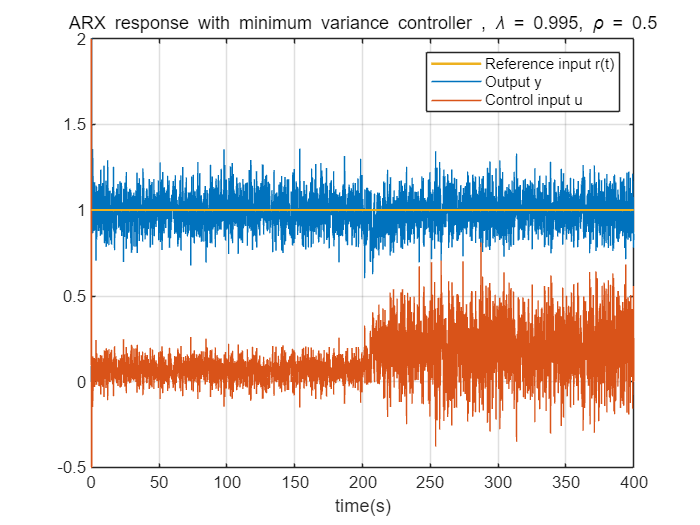

rng(0);
% ARX_model
timestep_T = 0.1;
N = 400;
time = linspace(0, N, N/timestep_T + 1);
output_data = zeros([length(time), 1]);
input_data = zeros([length(time), 1]);

output_y = 0;                   % y(t)
prev_output_y = 0;              % y(t-1)
input_r = 1;                    %%%% Unit step input %%%%
input_u = 0.1;                    % Initial input u
noise_nu = 0.1;                 % Gaussian noise with zero mean, 0.1 std
rho_P = 0.5.*eye(2);             % Covariance matrix 
prev_rho_P = rho_P;             % Previous covariance matrix
hat_theta = zeros([2, 1]);      % Initial model parameter
hat_theta_prev = hat_theta;     % Previous model parameter
hat_theta_data = [];            % Empty array for collecting data
recursive_H = zeros([1, 2]);    % Recursive model parameter
error = 0;                      % Initializing error
lambda = 0.995;
for t = 1 : length(time)
    if (t + 1 > length(time))
        break;
    end
    if t <= (length(time)-1)/2
        b_0 = 1.5;
    else
        b_0 = 0.5;
    end
   
    output_y = 0.9*prev_output_y + b_0*input_u + noise_nu*randn;
    % step input에 대한 ARX model의 output data계산
    recursive_H = [prev_output_y, input_u];
    error = output_y - recursive_H*hat_theta_prev;
    % Calculate error
    rho_P = (prev_rho_P - prev_rho_P*recursive_H'/(lambda + recursive_H*prev_rho_P*recursive_H')*recursive_H*prev_rho_P)./lambda;
    % Update P
    K = prev_rho_P*recursive_H'/(1 + recursive_H*prev_rho_P*recursive_H');
    % Update gain K
    hat_theta = hat_theta_prev + K*error;
    % Update estimated theta
    output_data(t+1) = output_y;
    input_data(t) = input_u;
    prev_input = input_u;
    prev_output_y = output_y;
    prev_rho_P = rho_P;
    hat_theta_prev = hat_theta;
    hat_theta_data = [hat_theta_data, hat_theta];
    % Stack estimated theta data
    input_u = (input_r - output_y*hat_theta(1))/hat_theta(2);
    % Update input u for next iteration
end

Output_y = plot(time(1:length(input_data)), output_data);
hold on; grid on;
Ctrl_input = plot(time(1:length(input_data)), input_data);
Ref_input = plot(time(1:length(input_data)), input_r*ones([length(input_data), 1]), "LineWidth", 1.5);
ylim([-0.5, 2]);
legend([Ref_input, Output_y, Ctrl_input], {"Reference input r(t)", "Output y", "Control input u"});
xlabel("time(s)"); title("ARX response with minimum variance controller , \lambda = 0.995, \rho = 0.5");
hold off;

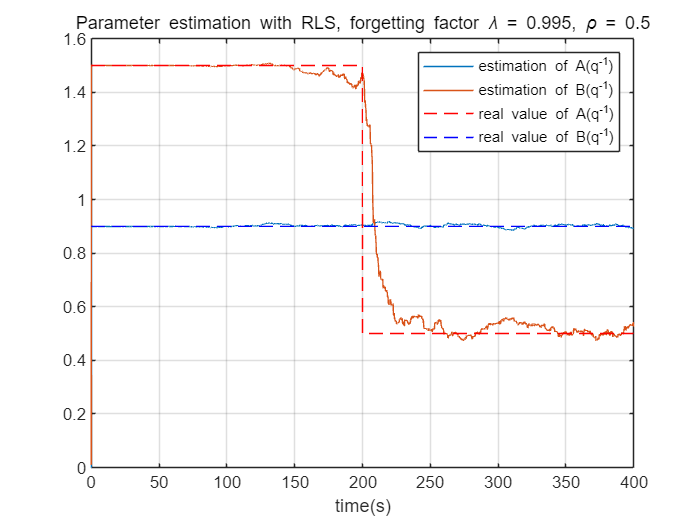

estimation_Aq = plot(time(1:length(hat_theta_data)), hat_theta_data(1,:));
hold on; grid on
estimation_Bq = plot(time(1:length(hat_theta_data)), hat_theta_data(2,:));
real_a1 = plot(time(1:length(hat_theta_data)), [1.5*ones([length(hat_theta_data)/2, 1]); 0.5*ones([length(hat_theta_data)/2, 1])], 'r--');
real_b1 = plot(time(1:length(hat_theta_data)), 0.9*ones([length(hat_theta_data), 1]), 'b--');
legend([estimation_Aq, estimation_Bq, real_a1, real_b1], {"estimation of A(q^{-1})", "estimation of B(q^{-1})", "real value of A(q^{-1})", "real value of B(q^{-1})"}, 'Location', 'northeast');
xlabel("time(s)"); title("Parameter estimation with RLS, forgetting factor \lambda = 0.995, \rho = 0.5");
hold off;

아래의 $\hat{a}_0$, $\hat{b}_0$ 추정 그래프와 $A(q^{-1})$ 추정의 RMSE는 $0.1252$이고, $B(q^{-1})$ 추정의 RMSE는 $0.0209$임을 통해 RLS가 적절하게 model parameter들을 추정하는 것을 확인할 수 있다. 하지만, 위 step input에 대해서 ARX 모델의 output이 1을 중심으로 noise가 섞인 모습을 확인할 수 있다. 이는 ARX 모델 자체에서 output $y$가 0.1의 표준편차를 가진 랜덤한 노이즈에 직접적인 영향을 받기 때문에 나타난 현상이라고 해석할 수 있다.

### b)

$r(t) = \sin\left(\frac{\omega t}{5}\right)$, $\omega = 0.2, 1, 5$에 대한 Minimum variance controller 를 설계하여라.

***sol)***

위 **a)**의 방식으로 Minimum variance controller 설계를 진행한다. Forgetting factor $\lambda$와 covariance matrix $\rho$의 값은 **a)**의 값을 그대로 채택해 사용했다.

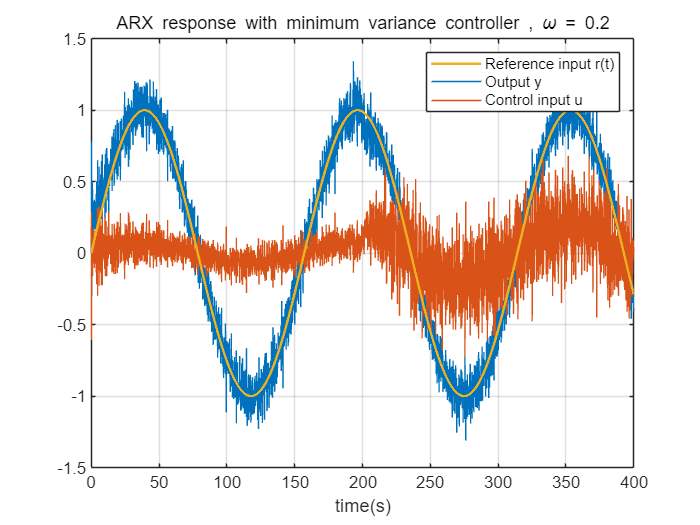

omega = 0.2;                    % omega = 0.2
[input_data, output_data, input_r, hat_theta_data] = prob_b(time, omega);
Output_y = plot(time(1:length(input_data)), output_data);
hold on; grid on;
Ctrl_input = plot(time(1:length(input_data)), input_data);
Ref_input = plot(time(1:length(input_data)), input_r, "LineWidth", 1.5);
% ylim([-0.5, 2]);
legend([Ref_input, Output_y, Ctrl_input], {"Reference input r(t)", "Output y", "Control input u"});
xlabel("time(s)"); title("ARX response with minimum variance controller , \omega = 0.2");
hold off;

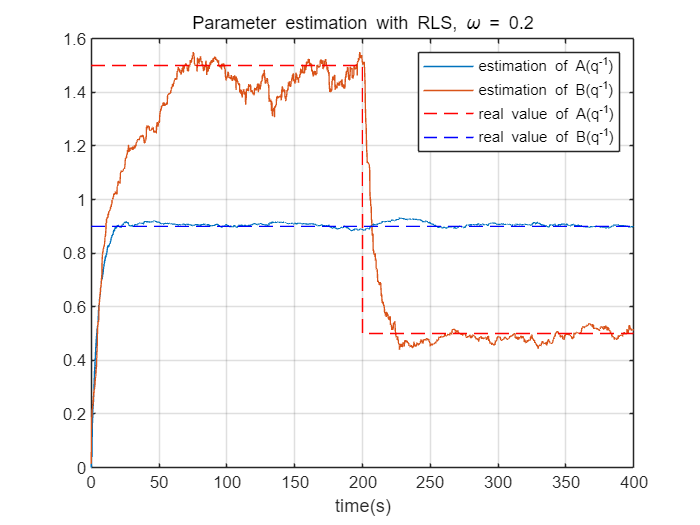

estimation_Aq = plot(time(1:length(hat_theta_data)), hat_theta_data(1,:));
hold on; grid on
estimation_Bq = plot(time(1:length(hat_theta_data)), hat_theta_data(2,:));
real_a1 = plot(time(1:length(hat_theta_data)), [1.5*ones([length(hat_theta_data)/2, 1]); 0.5*ones([length(hat_theta_data)/2, 1])], 'r--');
real_b1 = plot(time(1:length(hat_theta_data)), 0.9*ones([length(hat_theta_data), 1]), 'b--');
legend([estimation_Aq, estimation_Bq, real_a1, real_b1], {"estimation of A(q^{-1})", "estimation of B(q^{-1})", "real value of A(q^{-1})", "real value of B(q^{-1})"}, 'Location', 'northeast');
xlabel("time(s)"); title("Parameter estimation with RLS, \omega = 0.2");
hold off;

data_RMSE(hat_theta_data)

ans =     0.5276
    0.4576


$\hat{a}_0$, $\hat{b}_0$의 추정 RMSE는 각각 $0.5276$, $0.4576$이다.

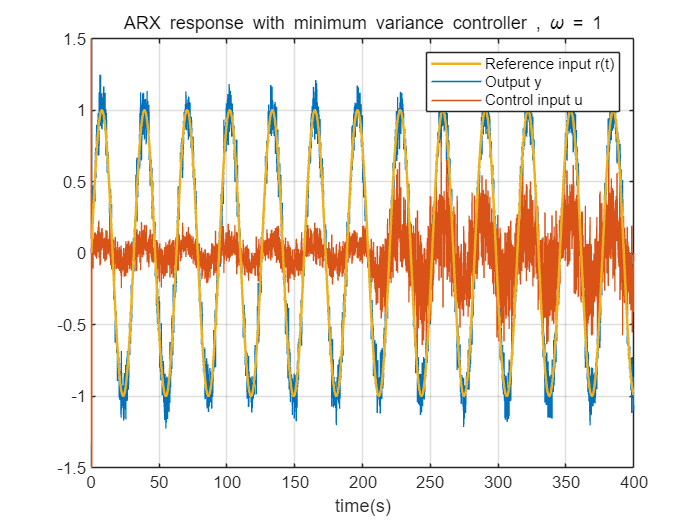

omega = 1;                    % omega = 1
[input_data, output_data, input_r, hat_theta_data] = prob_b(time, omega);
Output_y = plot(time(1:length(input_data)), output_data);
hold on; grid on;
Ctrl_input = plot(time(1:length(input_data)), input_data);
Ref_input = plot(time(1:length(input_data)), input_r, "LineWidth", 1.5);
ylim([-1.5, 1.5]);
legend([Ref_input, Output_y, Ctrl_input], {"Reference input r(t)", "Output y", "Control input u"});
xlabel("time(s)"); title("ARX response with minimum variance controller , \omega = 1");
hold off;

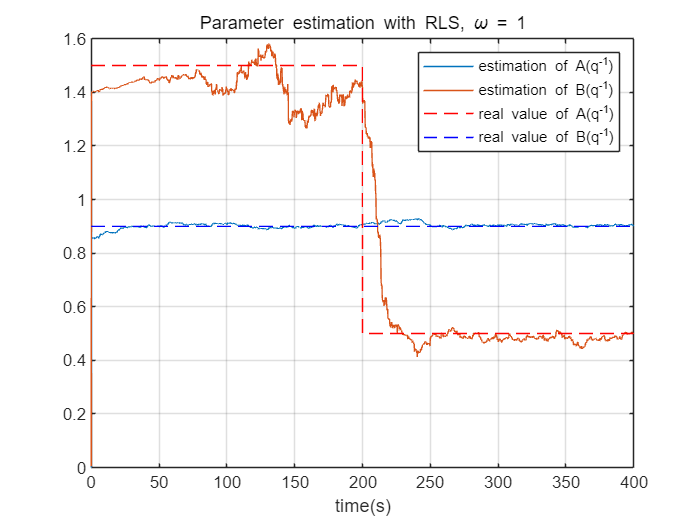

estimation_Aq = plot(time(1:length(hat_theta_data)), hat_theta_data(1,:));
hold on; grid on
estimation_Bq = plot(time(1:length(hat_theta_data)), hat_theta_data(2,:));
real_a1 = plot(time(1:length(hat_theta_data)), [1.5*ones([length(hat_theta_data)/2, 1]); 0.5*ones([length(hat_theta_data)/2, 1])], 'r--');
real_b1 = plot(time(1:length(hat_theta_data)), 0.9*ones([length(hat_theta_data), 1]), 'b--');
legend([estimation_Aq, estimation_Bq, real_a1, real_b1], {"estimation of A(q^{-1})", "estimation of B(q^{-1})", "real value of A(q^{-1})", "real value of B(q^{-1})"}, 'Location', 'northeast');
xlabel("time(s)"); title("Parameter estimation with RLS, \omega = 1");
hold off;

data_RMSE(hat_theta_data)

ans =     0.5144
    0.4708


$\hat{a}_0$, $\hat{b}_0$의 추정 RMSE는 각각 $0.5144$, $0.4708$이다.

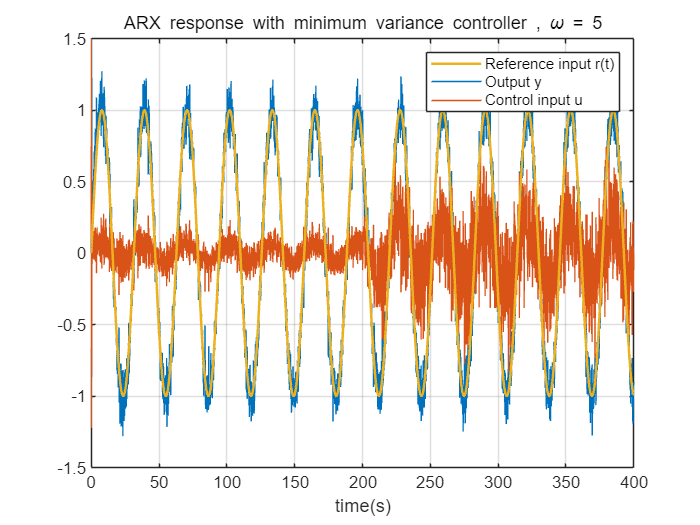

omega = 1;                    % omega = 5
[input_data, output_data, input_r, hat_theta_data] = prob_b(time, omega);
Output_y = plot(time(1:length(input_data)), output_data);
hold on; grid on;
Ctrl_input = plot(time(1:length(input_data)), input_data);
Ref_input = plot(time(1:length(input_data)), input_r, "LineWidth", 1.5);
ylim([-1.5, 1.5]);
legend([Ref_input, Output_y, Ctrl_input], {"Reference input r(t)", "Output y", "Control input u"});
xlabel("time(s)"); title("ARX response with minimum variance controller , \omega = 5");
hold off;

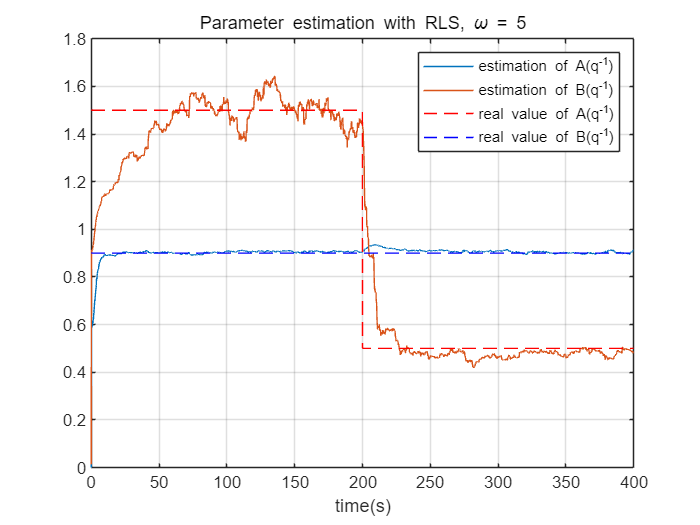

estimation_Aq = plot(time(1:length(hat_theta_data)), hat_theta_data(1,:));
hold on; grid on
estimation_Bq = plot(time(1:length(hat_theta_data)), hat_theta_data(2,:));
real_a1 = plot(time(1:length(hat_theta_data)), [1.5*ones([length(hat_theta_data)/2, 1]); 0.5*ones([length(hat_theta_data)/2, 1])], 'r--');
real_b1 = plot(time(1:length(hat_theta_data)), 0.9*ones([length(hat_theta_data), 1]), 'b--');
legend([estimation_Aq, estimation_Bq, real_a1, real_b1], {"estimation of A(q^{-1})", "estimation of B(q^{-1})", "real value of A(q^{-1})", "real value of B(q^{-1})"}, 'Location', 'northeast');
xlabel("time(s)"); title("Parameter estimation with RLS, \omega = 5");
hold off;

data_RMSE(hat_theta_data)

ans =     0.5157
    0.4865


$\hat{a}_0$, $\hat{b}_0$의 추정 RMSE는 각각 $0.5157$, $0.4865$이다.

Forgetting factor를 적용한 RLS 기반의 dynamics inversion law control이 sinusoidal reference에 대해서도 적절하게 추종하는 모습을 확인할 수 있다.

## Function

- 2 - b) problem function

function [input_data, output_data, input_r, hat_theta_data] = prob_b(time, omega)
    output_data = zeros([length(time), 1]);
    input_data = zeros([length(time), 1]);
    
    output_y = 0;                   % y(t)
    prev_output_y = 0;              % y(t-1)
    input_r = sin(omega*time/5);    %%%% Sinusoidal input %%%%
    input_u = 0.1;                  % Initial input u
    noise_nu = 0.1;                 % Gaussian noise with zero mean, 0.1 std
    rho_P = 0.5.*eye(2);             % Covariance matrix 
    prev_rho_P = rho_P;             % Previous covariance matrix
    hat_theta = zeros([2, 1]);      % Initial model parameter
    hat_theta_prev = hat_theta;     % Previous model parameter
    hat_theta_data = [];            % Empty array for collecting data
    recursive_H = zeros([1, 2]);    % Recursive model parameter
    error = 0;                      % Initializing error
    lambda = 0.995;
    for t = 1 : length(time)
        if (t + 1 > length(time))
            break;
        end
        if t <= (length(time)-1)/2
            b_0 = 1.5;
        else
            b_0 = 0.5;
        end
       
        output_y = 0.9*prev_output_y + b_0*input_u + noise_nu*randn;
        % step input에 대한 ARX model의 output data계산
        recursive_H = [prev_output_y, input_u];
        error = output_y - recursive_H*hat_theta_prev;
        % Calculate error
        rho_P = (prev_rho_P - prev_rho_P*recursive_H'/(lambda + recursive_H*prev_rho_P*recursive_H')*recursive_H*prev_rho_P)./lambda;
        % Update P
        K = prev_rho_P*recursive_H'/(1 + recursive_H*prev_rho_P*recursive_H');
        % Update gain K
        hat_theta = hat_theta_prev + K*error;
        % Update estimated theta
        output_data(t+1) = output_y;
        input_data(t) = input_u;
        prev_input = input_u;
        prev_output_y = output_y;
        prev_rho_P = rho_P;
        hat_theta_prev = hat_theta;
        hat_theta_data = [hat_theta_data, hat_theta];
        % Stack estimated theta data
        input_u = (input_r(t+1) - output_y*hat_theta(1))/hat_theta(2);
        % Update input u for next iteration
    end
end

function RMSE = data_RMSE(hat_theta_data)
Real_A1 = [1.5*ones([length(hat_theta_data)/2, 1]); 0.5*ones([length(hat_theta_data)/2, 1])]';
Real_B1 = 0.9*ones([length(hat_theta_data), 1])';
RMSE = [sqrt(sum((hat_theta_data(1,:) - Real_A1).^2)/4000); sqrt(sum((hat_theta_data(2,:) - Real_B1).^2)/4000)];
end